# ARbot_Rev2_1 ik Verification

Create a generalized inverse kinematics solver that holds a robotic arm at a specific location and points toward the robot base. Create the constraint objects to pass the necessary constraint parameters into the solver.

Load predefined ARbot robot model, which is specified as a `rigidBodyTree` object.

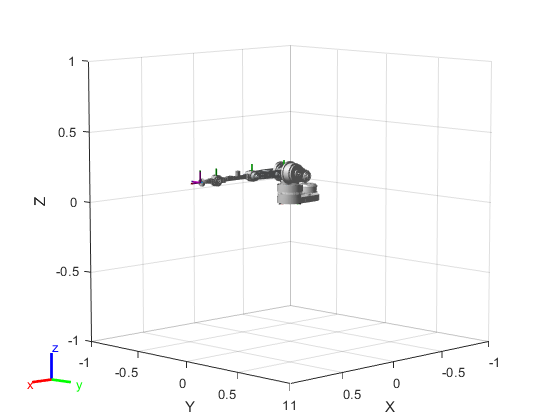

clear all
close all
robot=importrobot('Arbot_Rev2_1.urdf');
% Add gravity
gravityVec = [0 0 -9.80665];
robot.Gravity = gravityVec; 
inch = 0.0254;
half_inch = inch / 2;
% Add another massless coordinate frame for the end effector

eeOffset = 0.150;
eeBody = robotics.RigidBody('end_effector');
eeBody.Mass = 0;
eeBody.Inertia = [0 0 0 0 0 0];
setFixedTransform(eeBody.Joint,trvec2tform([eeOffset 0 0]));
figure(1);
addBody(robot,eeBody,'L4');
pose = robot.homeConfiguration;
pose(1).JointPosition = 0;
pose(2).JointPosition = pi/4;
pose(3).JointPosition = pi/4;
pose(4).JointPosition = pi/4;
axes=show(robot,'Frames',"off"); 
axes.CameraPositionMode = 'auto';

## Load Key Waypoints

% NOT FLIPPED X AND Y TO ACCOUNT FOR MATLAB REFERENCE FRAME
P_A_BORG_65 = [ 0.2205 0.5588 -0.3135];
P_A_BORG_75 = [0.5024 0.5588 -0.2109];
P_A_BORG_8 = [0.6434 0.5588 -0.1596];
P_A_BORG_9 = [0.9253 0.5588 -0.0570];

% FLIP X AND Y TO ACCOUNT FOR MATLAB REFERENCE FRAME
P_A_BORG_65 = [ -0.5588 -0.2205 -0.3135];
P_A_BORG_75= [-0.5588 -0.5024 -0.2109]; % 2nd furthest 9.75
P_A_BORG_8 = [ -0.5588; -0.6434; -0.1596 ]; % furthest from the robot 9.8
P_A_BORG_9 = [ -0.5588; -0.9253; -0.0570 ]; % furthest from the robot 9.9

% corners for the end point

%% 75
P_B = [ 0; 0; 0; 1;];
T_A_B(1:3,1:3) = [   0.0000    0.9397   -0.3420;
                   -1.0000    0.0000         0;
                         0    0.3420    0.9397;];
T_A_B(1:3,4) = P_A_BORG_75;
P_A = T_A_B * P_B; % vector from the base of the robot to the target
% get joint angles for each point
P_end = P_A;
P_end(1) = -P_end(1);
P_mid_75 = midpoint(P_A,P_end);

%% 8
P_B = [ 0; 0; 0; 1;];
T_A_B(1:3,1:3) = [   0.0000    0.9397   -0.3420;
                   -1.0000    0.0000         0;
                         0    0.3420    0.9397;];
T_A_B(1:3,4) = P_A_BORG_8;
P_A = T_A_B * P_B; % vector from the base of the robot to the target
% get joint angles for each point
P_end = P_A;
P_end(1) = -P_end(1);
P_mid_8 = midpoint(P_A,P_end);

%% 9
P_B = [ 0; 0; 0; 1;];
T_A_B(1:3,1:3) = [   0.0000    0.9397   -0.3420;
                   -1.0000    0.0000         0;
                         0    0.3420    0.9397;];
T_A_B(1:3,4) = P_A_BORG_9;
P_A = T_A_B * P_B; % vector from the base of the robot to the target

% get joint angles for each point
P_end = P_A;
P_end(1) = -P_end(1);
P_mid_9 = midpoint(P_A,P_end);

## Determine Equation of Line 

% solve for slope and angle
delta = P_mid_9 - P_mid_8;
slope = delta(3) / delta(2);
angle = atand(slope);
% solve for eqn y = m(x) + b
b =  P_mid_9(3) - slope * P_mid_9(2);
% anonymous function for slope
conveyorBeltEqn = @(x) slope*x + b;

% generate line along the conveyor belt
rangeAlongConveyorToTest = linspace(P_mid_9(2),P_mid_8(2),8);
y_int = conveyorBeltEqn(0);
pointsAlongLine = [];
for i=1:length(rangeAlongConveyorToTest)
    new_z = conveyorBeltEqn(rangeAlongConveyorToTest(i));
    point = [ 0 rangeAlongConveyorToTest(i) new_z];
    pointsAlongLine = [ pointsAlongLine; point];
end

% generate line along the conveyor belt CORNERS
corner_range = P_mid_9(2) - P_mid_8(2);
rangeAlongCornerToTest = linspace(P_A_BORG_65(2)+corner_range,P_A_BORG_65(2),8);
pointsAlongLineCorner = [];
for i=1:length(rangeAlongCornerToTest)
    new_z = conveyorBeltEqn(rangeAlongCornerToTest(i));
    point = [ P_A_BORG_65(1) rangeAlongCornerToTest(i) new_z ];
    pointsAlongLineCorner = [ pointsAlongLineCorner; point];
end
pointsAlongLineCornerReflected = [ -pointsAlongLineCorner(:,1) pointsAlongLineCorner(:,2) pointsAlongLineCorner(:,3)];

angleInRadians = deg2rad(-70);
wayPoints = [ P_A_BORG_65(1) P_A_BORG_65(2) P_A_BORG_65(3);
   -P_A_BORG_65(1) P_A_BORG_65(2) P_A_BORG_65(3);   
      P_mid_75;
      P_mid_8;
      P_mid_9;
      pointsAlongLine;
      pointsAlongLineCorner;
      pointsAlongLineCornerReflected ;
      ];
% exampleHelperPlotWaypoints(wayPoints);
hold on

% create body string array

## Repeat transforms for all points

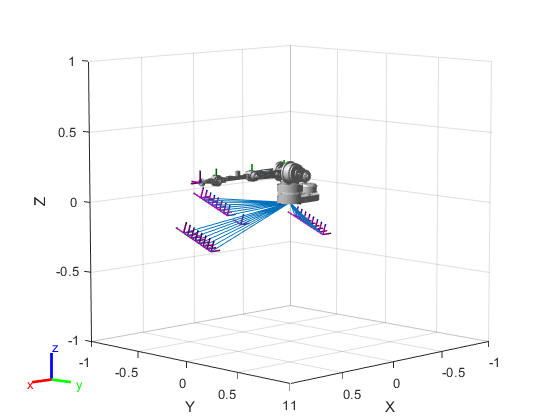

refBodyStrings = {};
ROTX = rotx(20);
ROTZ = rotz(180);
for i=1:length(wayPoints)
    targetString = 'targetFrame';
    chr = int2str(i);
    targetString = append(targetString,chr); % generate different strings for different rigid bodies
    refBodyStrings{end + 1} = targetString;
    body = rigidBody(targetString); % use unique string to generate new rigid body
    tform = trvec2tform(wayPoints(i,:));
    tform(1:3,1:3) = tform(1:3,1:3) * ROTZ * ROTX ;
    setFixedTransform(body.Joint,tform);
    addBody(robot, body, robot.BaseName);
end
show(robot);

## Create Generalized IK

Create the System object™ for solving generalized inverse kinematics.

gik = generalizedInverseKinematics;

Configure the System object to use the KUKA robot robot.

gik.RigidBodyTree = robot;

Tell the solver to expect a `PositionTarget` object and a `constraintAiming` and `constraintPositionTarget` object as the constraint inputs.

gik.ConstraintInputs = {'position','aiming','joint'};

## Create Object Constraints

Create the two constraint objects.

- The origin of the body named `tool0` is located at `[0.0 0.5 0.5]` relative to the robot's base frame.

- The *z*-axis of the body named `tool0` points toward the origin of the robot's base frame.

% describe target position
gripper = 'end_effector';
posTgt = constraintPositionTarget(gripper);
posTgt.TargetPosition = wayPoints(1,:);
% position tolerance
posTgt.PositionTolerance = 0.005;

% Align with the conveyor belt and place a half inch above
aimCon = constraintAiming(gripper);
aimCon.ReferenceBody = 'targetFrame1';
aimCon.TargetPoint = [ 0 0 half_inch ];

jointConst = constraintJointBounds(robot);
jointConst.Bounds(1,:) = [-1.5 1.5];
jointConst.Bounds(2,:) = [ -0.1 1.5];
jointConst.Bounds

ans =    -1.5000    1.5000
   -0.1000    1.5000
   -3.1400    3.1400
   -3.1400    3.1400


show(robot);

Find a configuration that satisfies the constraints. You must pass the constraint objects into the System object in the order in which they were specified in the `ConstraintInputs` property. Specify an initial guess at the robot configuration.

q0 = homeConfiguration(robot); % Initial guess for solver
[q,solutionInfo] = gik(q0,posTgt,aimCon,jointConst);

Visualize the configuration returned by the solver.

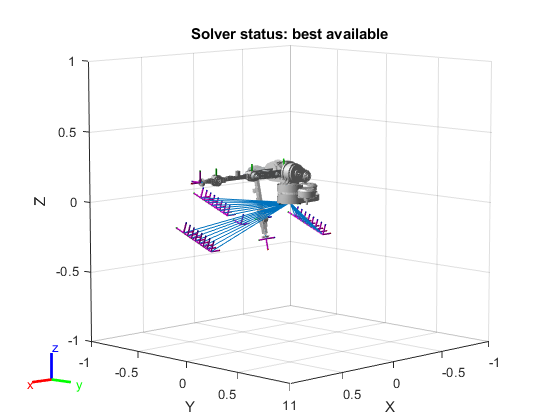

show(robot,q);
title(['Solver status: ' solutionInfo.Status])

## solve ik for all points along wayPoints

% for i = 1:length(wayPoints)
%     % describe target position
%     gripper = 'end_effector';
%     posTgt = constraintPositionTarget(gripper);
%     posTgt.TargetPosition = wayPoints(i,:);
%     % position tolerance
%     posTgt.PositionTolerance = 0.005;
%     % Align with the conveyor belt and place a half inch above
%     aimCon = constraintAiming(gripper);
%     aimCon.ReferenceBody = char(refBodyStrings(i));
%     aimCon.TargetPoint = [ 0 0 half_inch ];
%     q0 = homeConfiguration(robot); % Initial guess for solver
%     [q,solutionInfo] = gik(q0,posTgt,aimCon);
%     show(robot,q,'Frames','off');
%     title(['Solver status: ' solutionInfo.Status])
% end

## Safe Via Point Joint Angles

% safe_via = [ -0.2512 ; -0.5558;  0.2; ];
% % safe_via = [ -0.5558/2; -0.5; 0.1; ];
% posTgt = constraintPositionTarget(gripper);
% aimCon.ReferenceBody = 'base_link';
% posTgt.TargetPosition = safe_via;
% % aimCon = constraintAiming(gripper);
% aimCon.TargetPoint = safe_via;
% q0 = homeConfiguration(robot); % Initial guess for solver
% [q,solutionInfo] = gik(q0,posTgt,aimCon);
% safe_via_angles = [];
% safe_via_angles(1,1) = q(1).JointPosition;
% safe_via_angles(1,2) = q(2).JointPosition;
% safe_via_angles(1,3) = q(3).JointPosition;
% safe_via_angles(1,4) = q(4).JointPosition;
% show(robot,q, 'PreservePlot', true,'Frames','on');

## Circle fit and visualize workspaces

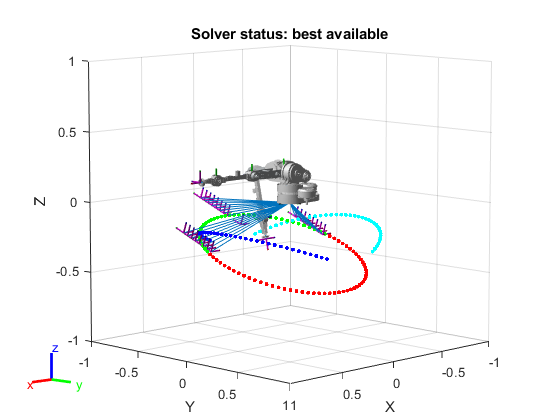

%% fit and plot
[center,rad,v1,v2] = circlefit3d(pointsAlongLineCorner(6,:),...
                                 P_mid_8(1,:),...
                                 pointsAlongLineCornerReflected(6,:));
idx = 1;
for i=1:4:361
    a = i/180*pi;
    x = center(:,1)+sin(a)*rad.*v1(:,1)+cos(a)*rad.*v2(:,1);
    y = center(:,2)+sin(a)*rad.*v1(:,2)+cos(a)*rad.*v2(:,2);
    z = center(:,3)+sin(a)*rad.*v1(:,3)+cos(a)*rad.*v2(:,3);
    workspace_points(idx,:) = [ x y z ] ;
    plot3(x,y,z,'r.');
    idx = idx + 1;
end

%% filter workspace to relevant parts
indices_of_workspace = find(workspace_points(:,3)>wayPoints(1,3));
filtered_workspace = workspace_points(indices_of_workspace,:);
filtered_workspace = sortrows(filtered_workspace);
for i=1:length(indices_of_workspace)
    a = i/180*pi;
    x = filtered_workspace(i,1);
    y = filtered_workspace(i,2);
    z = filtered_workspace(i,3);
    plot3(x,y,z,'g.');
    pause(0.01);
    idx = idx + 1;
end
hold on
%% convert points from world to robot POV

corrected_workspace(:,1) = filtered_workspace(:,2);
corrected_workspace(:,2) = filtered_workspace(:,1);
corrected_workspace(:,3) = filtered_workspace(:,3);
% points are now corrected, to be in the robot POV

for i=1:length(indices_of_workspace)
    a = i/180*pi;
    x = corrected_workspace(i,1);
    y = corrected_workspace(i,2);
    z = corrected_workspace(i,3);
    plot3(x,y,z,'c.');
    pause(0.01);
    idx = idx + 1;
end

%% plot filtered (in front of robot)
P_A_BORG = [[0];[0];[0];]; % middle catch line, use 
P_B = [];
P_A = [];
for i=1:length(filtered_workspace)
    P_B(i,:) = [ filtered_workspace(i,1) filtered_workspace(i,2) filtered_workspace(i,3) 1];
    T_A_B(1:3,1:3) = rotz(90);
    T_A_B(1:3,4) = P_A_BORG;
    P_A(i,:) = T_A_B * P_B(i,:).';
end

for i=1:length(P_A)
    x = P_A(i,1);
    y = P_A(i,2);
    z = P_A(i,3);
    plot3(x,y,z,'b.');
    pause(0.01);
end

## Add reference bodies to each point along filtered

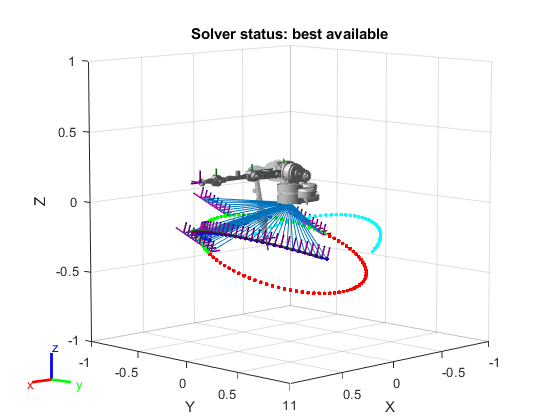

ROTX = rotx(20);
ROTZ = rotz(180 + 90);
workspaceRefBodyStrings = {};
for i=1:length(P_A)
    workspaceString = 'workspaceFrame';
    chr = int2str(i);
    workspaceString = append(workspaceString,chr); % generate different strings for different rigid bodies
    workspaceRefBodyStrings{end + 1} = workspaceString ;
    body = rigidBody(workspaceString); % use unique string to generate new rigid body
    tform = trvec2tform(P_A(i,1:3));
    tform(1:3,1:3) = tform(1:3,1:3) * ROTZ * ROTX ;
    setFixedTransform(body.Joint,tform);
    addBody(robot, body, robot.BaseName);
end
show(robot,'Frames','on');

## Create Generalized IK for the new points we just made

Create the System object™ for solving generalized inverse kinematics.

gik = generalizedInverseKinematics;

Configure the System object to use the KUKA robot robot.

gik.RigidBodyTree = robot;

Tell the solver to expect a `PositionTarget` object and a `constraintAiming` and `constraintPositionTarget` object as the constraint inputs.

gik.ConstraintInputs = {'position','aiming','joint'};

## Solve partially for new workspace

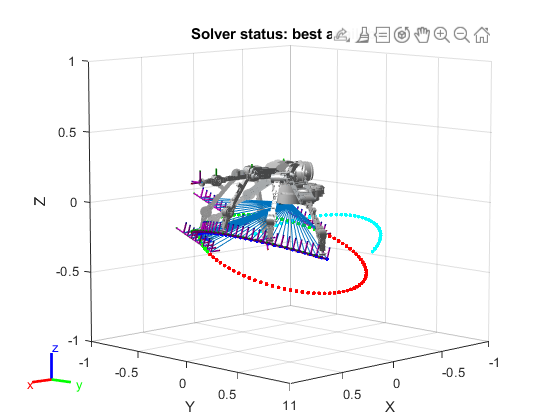

axes.CameraPositionMode = 'auto';
q = robot.homeConfiguration;
q(1).JointPosition = 0;
q(2).JointPosition = 0;
q(3).JointPosition = 0;
q(4).JointPosition = 0;
for i = 1:floor(1/4*length(P_A)):length(P_A);
    gripper = 'end_effector';
    posTgt = constraintPositionTarget(gripper);
    posTgt.TargetPosition = P_A(i,1:3);
    % position tolerance
    posTgt.PositionTolerance = 0.005;
    % Align with the conveyor belt and place a half inch above
    aimCon = constraintAiming(gripper);
    aimCon.ReferenceBody = char(workspaceRefBodyStrings(i));
    aimCon.TargetPoint = [ 0 0 half_inch ];
    
    if i < floor(1/4*length(P_A))
       jointConst.Bounds(2,:) =  [ -3.14 3.14];
    elseif i > floor(3/4*length(P_A))
       jointConst.Bounds(2,:) = [ -3.14 3.14];
    else
       jointConst.Bounds(2,:) = [ -0.1 1.5];
    end
    
    q0 = homeConfiguration(robot); % Initial guess for solver
    [q,solutionInfo] = gik(q0,posTgt,aimCon,jointConst);
    % q(1).JointPosition = q(1).JointPosition - pi/2;
    title(['Solver status: ' solutionInfo.Status])
    show(robot,q, 'PreservePlot', true,'Frames','off');
    hold on
end

## Solve all IK angles and Visualize

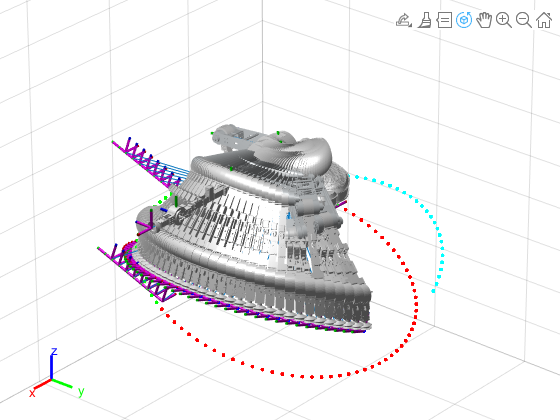

ikLookup = [];
% gik.RigidBodyTree = robot;
for i = 1:size(P_A,1)
    gripper = 'end_effector';
    posTgt = constraintPositionTarget(gripper);
    posTgt.TargetPosition = P_A(i,1:3);
    % position tolerance
    posTgt.PositionTolerance = 0.005;
    % Align with the conveyor belt and place a half inch above
    aimCon = constraintAiming(gripper);
    aimCon.ReferenceBody = char(workspaceRefBodyStrings(i));
    aimCon.TargetPoint = [ 0 0 half_inch ];
    q0 = homeConfiguration(robot); % Initial guess for solver
    
    if i < floor(1/4*length(P_A))
        jointConst.Bounds(2,:) =  [ -3.14 3.14];
    elseif i > floor(3/4*length(P_A))
       jointConst.Bounds(2,:) = [ -3.14 3.14];
    else
       jointConst.Bounds(2,:) = [ -0.1 1.5];
    end
    
    [q,solutionInfo] = gik(q0,posTgt,aimCon,jointConst);
    show(robot,q,'Frames','off');
    % title(['Solver status: ' solutionInfo.Status])
    
    ikLookup(i,1) = q(1).JointPosition;
    ikLookup(i,2) = q(2).JointPosition;
    ikLookup(i,3) = q(3).JointPosition;
    ikLookup(i,4) = q(4).JointPosition;
    % show(robot,q, 'PreservePlot', true,'Frames','on');
    hold on
    % pause(0.01);
    % robot.plot(theta(idx));
end
hold off

## Save all workspace variables

save('ikLookupIterativeP_A_const.mat','ikLookup');
save('ARbot_workspace_iterative_P_A_const.mat','P_A');

## Helper Functions

function rot_z = rotz(ang)
    rot_z = [ cosd(ang) -sind(ang) 0;
                sind(ang) cosd(ang) 0 ;
                0 0 1;];
end

function rot_x = rotx(ang)
        rot_x = [ 1 0 0;
        0 cosd(ang) -sind(ang);
        0 sind(ang) cosd(ang);];
end

function P_mid = midpoint(P1,P2)
    P_mid(1) = (P1(1) + P2(1)) / 2;
    P_mid(2) = (P1(2) + P2(2)) / 2;
    P_mid(3) = (P1(3) + P2(3)) / 2;
end

*Copyright 2019 The MathWorks, Inc.*